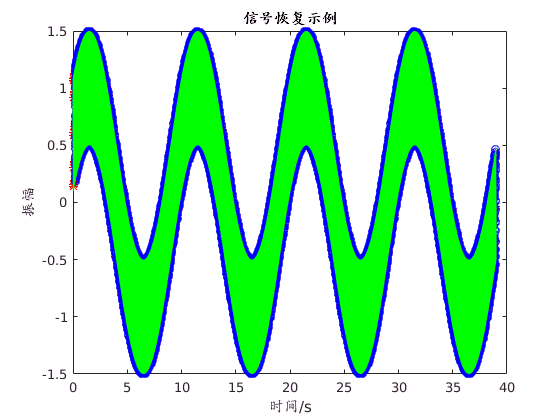

%向上重采样（由100sps增到500sps）
clearvars
orgInv    = 0.01;                             %原采样间隔（每秒100点） 
newInv    = 0.002;                            %新采样间隔（每秒500点）
orgDatLen = 4096;                             %原数据点数
newDatLen = floor(orgDatLen*orgInv/newInv);   %新数据点数
orgFs     = 1/orgInv;                         %原采样率
newFs     = 1/newInv;                         %新采样率
ratio     = newInv/orgInv;                    %新旧采样率比
orgCutFre = orgFs/2;                          %原截止频率=1/2采样率 
%--------------------------------------------------------------------------
figure

%--生成0.1Hz和30Hz的混合信号（30Hz信号振幅是0.1Hz信号振幅的1/2）,采用率为100---------
t100=(0:orgDatLen-1)/orgFs;
%t100=0:0.01:(orgDatLen-1);
mix100=sin(2*pi*0.1*t100)+0.5*sin(2*pi*30*t100);    
plot(t100(1:orgDatLen-orgFs-orgFs),mix100(1+orgFs:orgDatLen-orgFs),'r-*');
hold on

%--使用内差法从采样100的数据，向上重采样为500采样率数据-----------------------------
% Sinc是一个滤波器，它除去给定带宽之上的信号分量而只保留低频信号的理想电子滤波器。
% 理想的Sinc滤波器（矩形滤波器）,有无限的延迟，现实世界中的滤波器只能是它的一个近似。
comSta = orgFs+newFs+1;
comEnd = newDatLen-newFs-1;
difDat = zeros(1,comEnd);                     %初始化重采样序列
for m=comSta:comEnd
    for n=floor(m*ratio)-orgFs:floor(m*ratio)+orgFs
        difDat(m)=difDat(m)+mix100(n)*sinc(m*ratio-n);
    end
end

t500=(0:newDatLen-1)/newFs;
plot(t500(comSta-newFs-4:comEnd-newFs-4),difDat(comSta:comEnd)*zeta,'b-o');
hold on

%--生成0.1Hz和30Hz的混合信号（30Hz信号振幅是0.1Hz信号振幅的1/2）,采用率为1000--------
t1000=0:0.001:4000*orgInv-1;
mix1000=sin(2*pi*0.1*(t1000+1))+0.5*sin(2*pi*30*(t1000+1));
plot(t1000,mix1000,'g')
hold on

title('信号恢复示例')
xlabel('时间/s')
ylabel('振幅')